# Week 5: Inverse Kinematics

**Author: Keith Chester**

**E-mail: kchester@wpi.edu**

## **Introduction**

In the fourth week of *RBE 500 - Foundations of Robotics*, we are focusing on the application of inverse kinematics. For this assignment, we are looking at an example in the book (figure **5.4** and equations **5.40-5.42**) as explained in our book, *Robot Modeling and Control*, and graphically demonstrating principles taught within.

## **Methods**

The referenced image, **Figure 5.4**, shows an RRR arm.

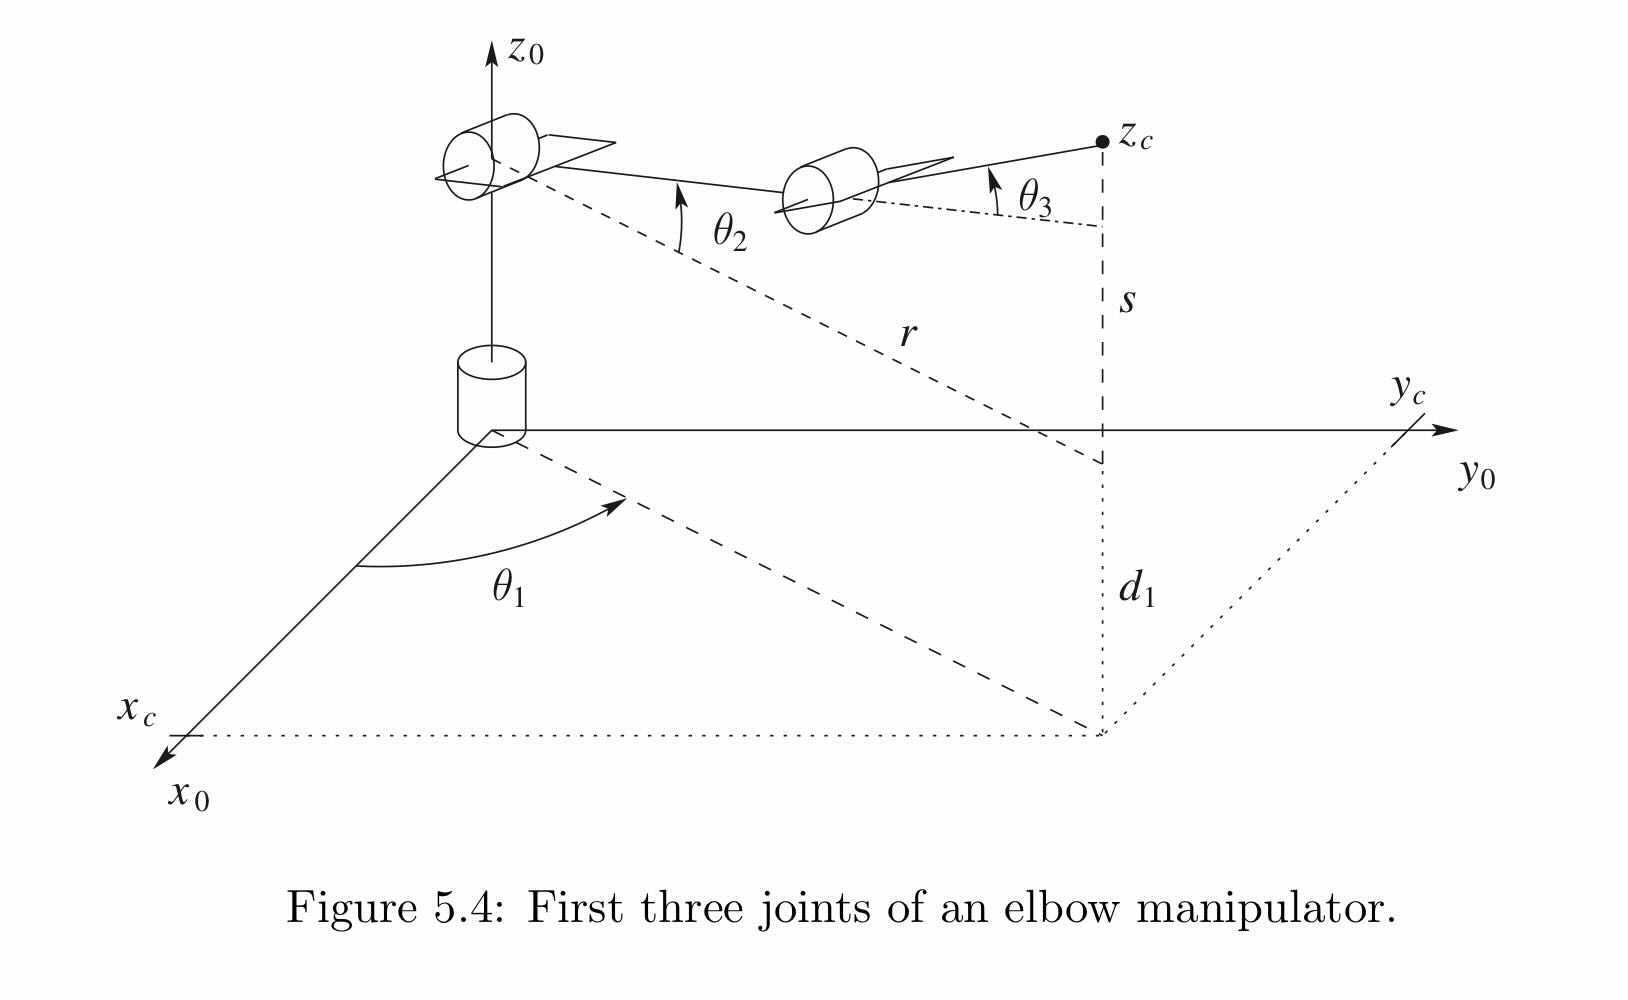

*Figure 1: Figure 5.4 from Robot Modeling and Control*

The equations within the book *Robot Modeling and Control*, **5.40 - 5.42**, referenced below respectively, are the results of using trigonometry (the defintion of * atan*, the *Pythagorean Theorom,*  and the *Law of Cosines*) to define the theta values for $\theta_1$, $\theta_2$, and $\theta_3$. Note that we have swapped the parameters to the *atan2 *function, as MATLAB's *atan2 *expects the parameters to be **y**, **x** vs the book's **x**, **y**.


$$\theta_1 =\textrm{atan2}\left(y_c ,x_c \right)$$


*Equation 1: *$\theta_1$* as per ****5.40***


$$\theta_2 =\textrm{atan2}\left({z_c -d}_1 ,\sqrt{x_c^2 +y_c^2 -d^2 }\right)-\textrm{atan2}\left(a_3 s_3 ,a_2 +a_3 \cos \left(\theta_3 \right)\right)$$


*Equation 2: *$\theta_2$ as per **5.41**


$$\begin{array}{l}
D=\frac{x_c^2 +y_c^2 -d^2 +{\left(z_c -d_1 \right)}^2 -a_2^2 -a_3^2 }{2a_2 a_3 }\\
\theta_3 =\textrm{atan2}\left(\pm \sqrt{1-D^2 },D\right)
\end{array}$$


*Equation 3: *$\theta_3$* as per ****5.42***

Our goal is to demonstrate through simulation that the analysis the book presents is accurate. To this end, first we must simulate the arm.

For this approach, we create the DH table for the arm for easier generation of needed transforms. Below, we see the DH table for the arm:

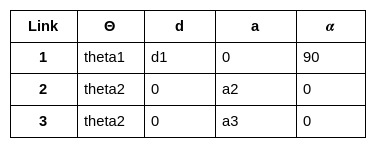

*Figure 2: The DH Table for the RRR arm in Figure 1*

Some of the values within the earlier listed equations are cancelled out as we have 0's in some of the DH table values. For values that are not variable, but not specified, such as **d1**, **a2**, and **a3**, we assign a simple value of 1 (for 1 meter) to keep calculations simple.

We then create a desired range of thetas using the *linspace *function. This creates an evenly spaced set of thetas to simulate over.

Finally, the animation. We define a desired length of the animation (5 seconds for this case). We then perform a "step" for each frame of the simulation:

- If this is not the first step, go through and erase all existing drawn lines in the figure to "clear" the canvas.

- We generate the DH table for this given step, grabbing each generated theta for the given step.

- From the DH table, we generate the needed transforms. First, we get $A_1$,$A_2$, and $A_3$, from the DH table via the traditional method of generating the transform matrix, as discssued within the function **transform_from_dh_values**. From this we can generate additional transforms we need to get our values back to frame 0: $H_1^0$,$H_2^0$, and $H_3^0$.

- Once we have the transforms, we draw the coordinate axis via the **draw_coordinate_axis** function.

- We then draw lines between the coordinate transforms to constitute the limbs of the robot.

- During the previous two steps, we keep track of the lines generated to clear out on the next step.

- We take not of the X, Y, and Z coordinates of the actuator at each stage for our next stage of analysis

- We pause a brief calculated time to ensure the simulation lasts the prescribed amount of time (5 seconds).

Once we have the simulation, we have a set of theta values for each joint, and then the resulting location of the actuator endpoint. We can then plot the location of the actuator making use of the calculations for each theta, working backwards from our generated value.

If the calculated thetas are accurately calculated, we should see a smooth linear increment in the theta value as *linspace* would generate. For this, we can just plot the thetas and see the expected values.

It should be noted that the arm does have singularities at certain thetas, which can result in calculated thetas that are undefined or incorrect for the given X, Y, and Z coordinates. As such, we avoided sending the arm over it's own head, for instance. We expect this to severely alter the behaviour of the inverse kinematics equations when $x_c =y_c =0$. We will demonstrate that below by purposefully sending the actuator over the robot's head.

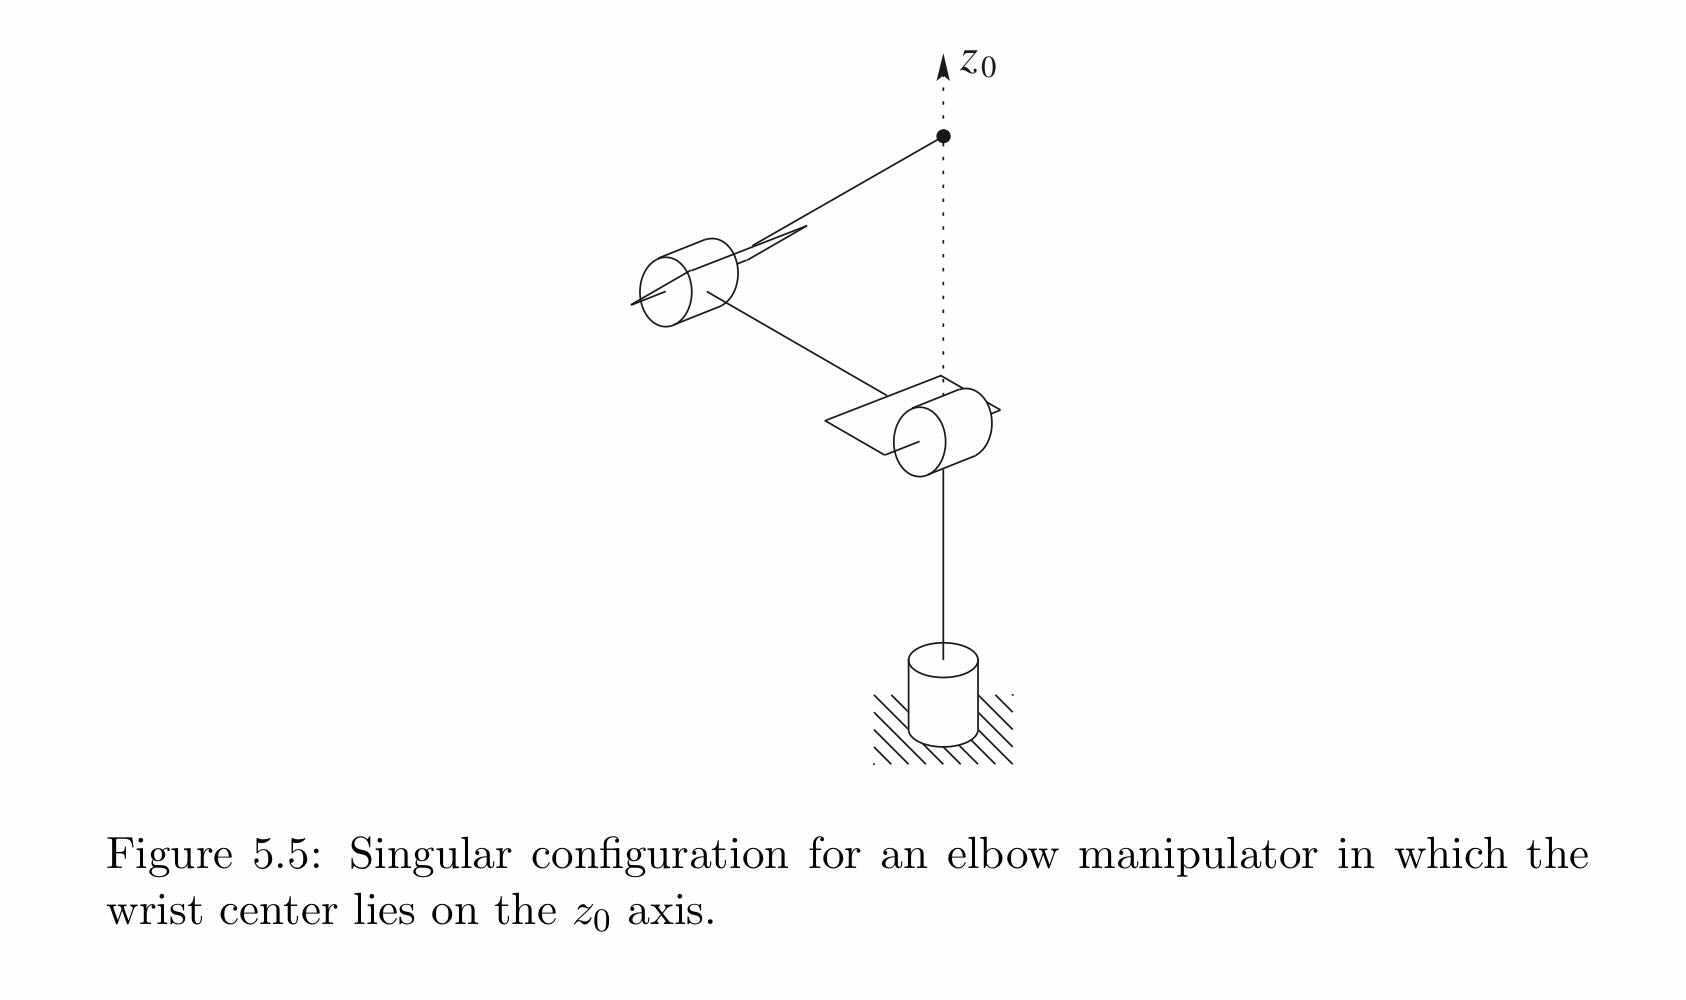

*Figure 3: Figure 5.5 from Robot Modeling and Control, demonstrating the point of singularity created when the actuator moves in line with the base z-axis*

## **Results**

For our approach, we will use the ***linspace*** function to generate a range of thetas that we will animate over. For our example, we'll be moving $\theta_1$from -20 to 0 degrees, $\theta_2$ from 0 to 60 degrees, and $\theta_3$ from 0 to 45 degrees.

theta1s = linspace(-20, 0, 100);
theta2s = linspace(0, 60, 100);
theta3s = linspace(0, 45, 100);

The arm's **d1**, **a2**, and **a3** are static lengths, but undefined. For our purposes, we shall give each an easy to use 1 meter for each length.

d1 = 1;
a2 = 1;
a3 = 1;

From here on out, we can generate the animation below. First, we'll move a controlled amount.

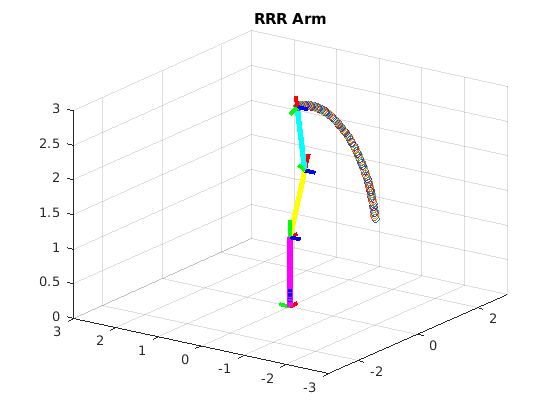


 

% Define our animation's figure settings
rrrfigure = figure;
title("RRR Arm")
grid on
hold on
axis([-3 3 -3 3 0 3])
view([45 25])
lines = [];
xs = [];
ys = [];
zs = [];
animation_length_seconds = 5;

% Perform our animation
for step = 1:length(theta1s)
    % Assign our theta for each step
    theta1 = theta1s(step);
    theta2 = theta2s(step);
    theta3 = theta3s(step);
    
    % For our theta values, create our DH Table for the arm in this
    % configuration
    dh_table = {  %theta        %d          %a      %alpha
            [     theta1        d1          0       90    ],
            [     theta2        0           a2      0     ],
            [     theta3        0           a3      0     ]   
           };
        
    % Find our transforms from the D_H table
    A_1 = transform_from_dh_row(dh_table, 1);
    A_2 = transform_from_dh_row(dh_table, 2);
    A_3 = transform_from_dh_row(dh_table, 3);
    
    % We need the transforms from the 0 frame for each coordinate axis to
    % map everything back to the same frame as the plot.
    H_0_1 = A_1;
    H_0_2 = A_1 * A_2;
    H_0_3 = A_1 * A_2 * A_3;
    
    % Clean up all existing lines from the previous animation step
    for index = 1:length(lines)
        delete(lines(index))
    end
    lines = [];
    
    % Draw coordinate axes
    [x_line, y_line, z_line] = draw_coordinate_axis(eye(4), 0.25, 'red', 'green', 'blue');
    lines(end+1) = x_line;
    lines(end+1) = y_line;
    lines(end+1) = z_line;
    [x_line, y_line, z_line] = draw_coordinate_axis(H_0_1, 0.25, 'red', 'green', 'blue');
    lines(end+1) = x_line;
    lines(end+1) = y_line;
    lines(end+1) = z_line;
    [x_line, y_line, z_line] = draw_coordinate_axis(H_0_2, 0.25, 'red', 'green', 'blue');
    lines(end+1) = x_line;
    lines(end+1) = y_line;
    lines(end+1) = z_line;
    [x_line, y_line, z_line] = draw_coordinate_axis(H_0_3, 0.25, 'red', 'green', 'blue');
    lines(end+1) = x_line;
    lines(end+1) = y_line;
    lines(end+1) = z_line;
    
    % Draw in the limbs now
    origin = [ 0; 0; 0; 1; ];
    elbow = H_0_1 * origin;
    wrist = H_0_2 * origin;
    actuator = H_0_3 * origin;
    lines(end+1) = line('XData', [origin(1) elbow(1)], 'YData', [origin(2) elbow(2)], 'ZData', [origin(3) elbow(3)], 'Color', 'magenta', 'LineWidth', 4);
    lines(end+1) = line('XData', [elbow(1) wrist(1)], 'YData', [elbow(2) wrist(2)], 'ZData', [elbow(3) wrist(3)], 'Color', 'yellow', 'LineWidth', 4);
    lines(end+1) = line('XData', [wrist(1) actuator(1)], 'YData', [wrist(2) actuator(2)], 'ZData', [wrist(3) actuator(3)], 'Color', 'cyan', 'LineWidth', 4);
    
    % Draw the actuator endpoint and save the (X,Y,Z) for this moment
    xs(end+1) = actuator(1);
    ys(end+1) = actuator(2);
    zs(end+1) = actuator(3);
    plot3(actuator(1), actuator(2), actuator(3), 'o')
    
    % Rotate the camera. Whee!
    camorbit(-1, 0)
    
    % Pause for the appropriate length of time to get our animation to 5
    % seconds
    pause(animation_length_seconds/length(theta1s))


end

hold off;

An example output of the above, here's the arm moving if it had moved 0 to 90 degrees for each theta:

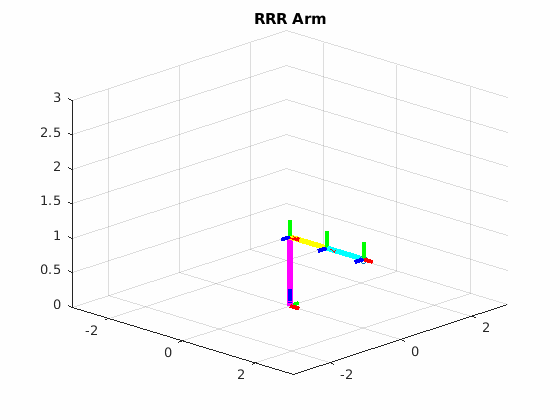

*Figure 4: The RRR arm animated with all thetas going 0-90 degrees*

Now we will be seeing if our calculated thetas, using *Equation 1-3*, and feeding in the recorded X, Y, and Z coordinates from the actuator endpoint in our movement, results in predictable and expected linearly increasing theta values. To do this, we'll be plotting the theta values for our movement.

First, we will perfom the calculations on *Equation 1*, *Equation 3*, and *Equation 2* in that order, since *Equation 2* depends upon the calculated value of $\theta_3$.

steps = linspace(1,length(theta1s), 100);
theta1s = atan2d(ys, xs);
D = (xs.^2 + ys.^2 + (zs-d1).^2 - a2^2 - a3^2) / (2*a2*a3);
theta3s = atan2d(sqrt(1-D.^2), D);
theta2s = atan2d(zs-d1, sqrt(xs.^2 + ys.^2)) - atan2d(a3*sind(theta3s), a2+a3*cosd(theta3s));

Once we have the calculated values, we can generate a plot below:

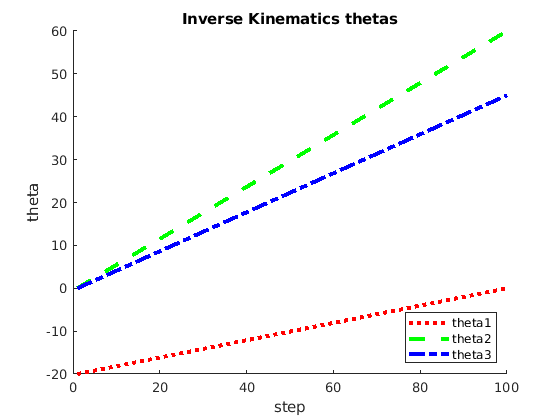

figure
title("Inverse Kinematics thetas")
xlabel("step")
ylabel("theta")
hold on;

plot(steps, theta1s, 'Color', 'r', 'LineStyle', ":", 'LineWidth', 3)

plot(steps, theta2s, 'Color', 'g', 'LineStyle', "--", 'LineWidth', 3)

plot(steps, theta3s, 'Color', 'b', 'LineStyle', "-.", "LineWidth", 3)

legend("theta1", "theta2", "theta3", "Location", "southeast")

hold off;

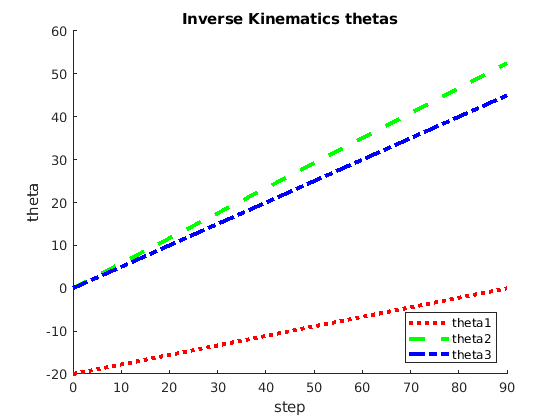

*Figure 5: The plotted calculated *$\theta_1$, $\theta_2$, and $\theta_3$

As predicted, we see a neatly linearly increasing value for each $\theta_1$, $\theta_2$, and $\theta_3$. We see $\theta_1$ increasing from -20 to 0, $\theta_2$ increasing from 0 to 60 degrees, and $\theta_3$ increasing from 0 to 45 degrees. The inverse calculations worked as expected.

However, as we discussed above in the **Methods** section, there exists a set of movements we can perform that will create singularities. This can be done either when the robot's actuator crosses overhead in line with the base z-axis, or when $x_c =y_c =0$. If this occurs, the equations can return infinitely many solutions, causing a noticeable jump and odd behaviour in the graph. Let's re-run the animations again, and look at the theta values for an arm experiencing the singularity.

Let's try the above process again, but with a singular value for all thetas - **0 ** to **90** degrees. This will cause the actuator to travel above the head of the robot, causing the singularity event.

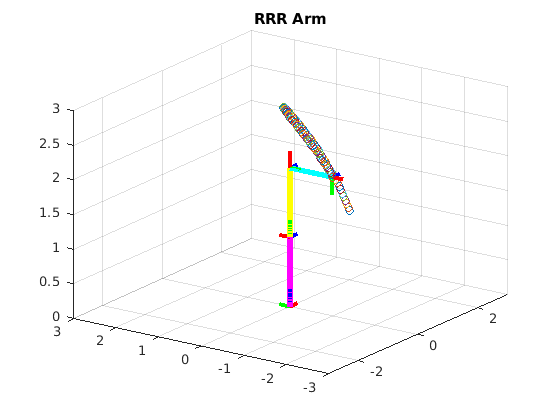

thetas = linspace(0, 90, 100);

 

% Define our animation's figure settings
rrrfigure = figure;
title("RRR Arm")
grid on
hold on
axis([-3 3 -3 3 0 3])
view([45 25])
lines = [];
xs = [];
ys = [];
zs = [];
animation_length_seconds = 5;

% Perform our animation
for step = 1:length(theta1s)
    % Assign our theta for each step
    theta = thetas(step);
    
    % For our theta values, create our DH Table for the arm in this
    % configuration
    dh_table = {  %theta        %d          %a      %alpha
            [     theta         d1          0       90    ],
            [     theta         0           a2      0     ],
            [     theta         0           a3      0     ]   
           };
        
    % Find our transforms from the D_H table
    A_1 = transform_from_dh_row(dh_table, 1);
    A_2 = transform_from_dh_row(dh_table, 2);
    A_3 = transform_from_dh_row(dh_table, 3);
    
    % We need the transforms from the 0 frame for each coordinate axis to
    % map everything back to the same frame as the plot.
    H_0_1 = A_1;
    H_0_2 = A_1 * A_2;
    H_0_3 = A_1 * A_2 * A_3;
    
    % Clean up all existing lines from the previous animation step
    for index = 1:length(lines)
        delete(lines(index))
    end
    lines = [];
    
    % Draw coordinate axes
    [x_line, y_line, z_line] = draw_coordinate_axis(eye(4), 0.25, 'red', 'green', 'blue');
    lines(end+1) = x_line;
    lines(end+1) = y_line;
    lines(end+1) = z_line;
    [x_line, y_line, z_line] = draw_coordinate_axis(H_0_1, 0.25, 'red', 'green', 'blue');
    lines(end+1) = x_line;
    lines(end+1) = y_line;
    lines(end+1) = z_line;
    [x_line, y_line, z_line] = draw_coordinate_axis(H_0_2, 0.25, 'red', 'green', 'blue');
    lines(end+1) = x_line;
    lines(end+1) = y_line;
    lines(end+1) = z_line;
    [x_line, y_line, z_line] = draw_coordinate_axis(H_0_3, 0.25, 'red', 'green', 'blue');
    lines(end+1) = x_line;
    lines(end+1) = y_line;
    lines(end+1) = z_line;
    
    % Draw in the limbs now
    origin = [ 0; 0; 0; 1; ];
    elbow = H_0_1 * origin;
    wrist = H_0_2 * origin;
    actuator = H_0_3 * origin;
    lines(end+1) = line('XData', [origin(1) elbow(1)], 'YData', [origin(2) elbow(2)], 'ZData', [origin(3) elbow(3)], 'Color', 'magenta', 'LineWidth', 4);
    lines(end+1) = line('XData', [elbow(1) wrist(1)], 'YData', [elbow(2) wrist(2)], 'ZData', [elbow(3) wrist(3)], 'Color', 'yellow', 'LineWidth', 4);
    lines(end+1) = line('XData', [wrist(1) actuator(1)], 'YData', [wrist(2) actuator(2)], 'ZData', [wrist(3) actuator(3)], 'Color', 'cyan', 'LineWidth', 4);
    
    % Draw the actuator endpoint and save the (X,Y,Z) for this moment
    xs(end+1) = actuator(1);
    ys(end+1) = actuator(2);
    zs(end+1) = actuator(3);
    plot3(actuator(1), actuator(2), actuator(3), 'o')
    
    % Rotate the camera. Whee!
    camorbit(-1, 0)
    
    % Pause for the appropriate length of time to get our animation to 5
    % seconds
    pause(animation_length_seconds/length(thetas))


end

hold off;

And, as before, we shall create plots of each theta valuie calculated from the actuator endpoints recorded during our submission.

steps = linspace(1,length(thetas), 100);
theta1s = atan2d(ys, xs);
D = (xs.^2 + ys.^2 + (zs-d1).^2 - a2^2 - a3^2) / (2*a2*a3);
theta3s = atan2d(sqrt(1-D.^2), D);
theta2s = atan2d(zs-d1, sqrt(xs.^2 + ys.^2)) - atan2d(a3*sind(theta3s), a2+a3*cosd(theta3s));

Once we have the calculated values, we can generate a plot below:

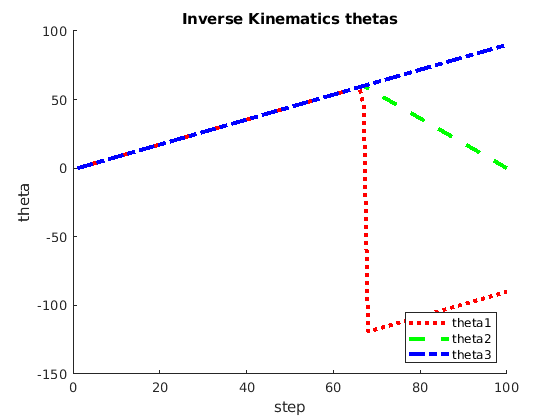

figure
title("Inverse Kinematics thetas")
xlabel("step")
ylabel("theta")
hold on;

plot(steps, theta1s, 'Color', 'r', 'LineStyle', ":", 'LineWidth', 3)

plot(steps, theta2s, 'Color', 'g', 'LineStyle', "--", 'LineWidth', 3)

plot(steps, theta3s, 'Color', 'b', 'LineStyle', "-.", "LineWidth", 3)

legend("theta1", "theta2", "theta3", "Location", "southeast")

hold off;

*Figure 6: The calculated *$\theta_1$*,*$\theta_2$*, and *$\theta_3$* values with a singularity occuring*

We can clearly see that, at a set point, both the $\theta_1$ and $\theta_2$ values dramatically change after the singularity,, with a near asymptopic result at the point of the singularity itself. Before this point, the thetas all overlap eachother, as expected.

This demonstrates that we must take care of utilizing the trigonometric approach for inverse kinematics to avoid singularities.

### Functions

Below are a collection of functions utilized to make the above code easier, repeatble, and more manageable.

#### transform_from_dh_values

This function takes the expected DH values - $\theta$, *d*, *a*, and $\alpha$. It then performs *Equation 1*, listed above.

The use of *vargin* is used to determine if an optional parameter is passed. This optional parameter is used to determine if the caller of the function wishes to make use of symbolic values. If so, we use *cos* and *sin* instead of *cosd *and *sind* respectively. This results in slightly better outputs for symbolic functions.

function H = transform_from_dh_values(theta, d, a, alpha, varargin)
    if nargin == 4
        R_z_theta = [ cosd(theta)      -sind(theta)     0     0;
                      sind(theta)       cosd(theta)     0     0;
                      0                 0               1     0;
                      0                 0               0     1; ];
        R_x_alpha = [ 1     0               0            0;
                      0     cosd(alpha)     -sind(alpha) 0;
                      0     sind(alpha)     cosd(alpha)  0;
                      0     0               0            1; ];
    else
        R_z_theta = [ cos(theta)      -sin(theta)     0     0;
                      sin(theta)       cos(theta)     0     0;
                      0                0              1     0;
                      0                0              0     1; ];
        R_x_alpha = [ 1     0              0            0;
                      0     cos(alpha)     -sin(alpha)  0;
                      0     sin(alpha)     cos(alpha)   0;
                      0     0              0            1; ];
    end
    
    
    T_z_d = [ 1     0      0    0;
              0     1      0    0;
              0     0      1    d;
              0     0      0    1; ];
    
    T_x_a = [ 1     0      0    a;
              0     1      0    0;
              0     0      1    0;
              0     0      0    1; ];
    
    
    
    H = R_z_theta * T_z_d * T_x_a * R_x_alpha;
end

#### transform_from_dh_row

This is a helper function that takes a DH table as defined above (in the form of a cell of matricies of expected DH values in a set standard order of $\theta$, *d*, *a*, and $\alpha$. It then separates out the $\theta$, *d*, *a*, and $\alpha$ of the specified row, and passes it to **transform_from_dh_values**, as described above. The use of *vargin* is passed through, for reasons specified above.

function H = transform_from_dh_row(table, row, vargin)
    theta = table{row}(1);
    d = table{row}(2);
    a = table{row}(3);
    alpha = table{row}(4);
    if nargin == 2
        H = transform_from_dh_values(theta, d, a, alpha);
    else
        H = transform_from_dh_values(theta, d, a, alpha, true);
    end
end

#### draw_coordinate_axis

This function accepts a specified transform, length of the desired axis lines, and the color for each axis. It then draws on the current active figure the origin for that axis based on the transform passed.

function [x_line, y_line, z_line] = draw_coordinate_axis(transform, length, x_color, y_color, z_color)    
    origin = transform * [0; 0; 0; 1;];
    x = transform * [length; 0;         0;      1; ];
    y = transform * [0;      length;    0;      1; ];
    z = transform * [0;      0;         length; 1; ];
    x_line = line('XData', [origin(1) x(1)], 'YData', [origin(2) x(2)], 'ZData', [origin(3) x(3)], 'Color', x_color, 'LineWidth', 3);
    y_line = line('XData', [origin(1) y(1)], 'YData', [origin(2) y(2)], 'ZData', [origin(3) y(3)], 'Color', y_color, 'LineWidth', 3);
    z_line = line('XData', [origin(1) z(1)], 'YData', [origin(2) z(2)], 'ZData', [origin(3) z(3)], 'Color', z_color, 'LineWidth', 3);
end

## Discussion

The assignment's purpose was to establish understanding of inverse kinematics by utilizing our simulation techniques to graphically demonstrate movement in an RRR robot arm, and then confirm the kinematic equations provided.

First we created a simulated plot of the robotic arm over a linearly increasing set of theta values. Over this time, we recorded the X, Y, and Z coordinates for the actuator position at each step.

Then, we utilized these coordinate values and the provided inverse kinematic equations to test if they are correct. To do so, we generate the calculated thetas from our list of observed coordinate positions. We then plot the calculated thetas to see if they are equvialent to the thetas we used.

This worked as long as we stayed away from singularities in the robot arm, such as directly above the arm. We then demonstrated what would occur to our calculations of theta if we did this - at the point of the singularity, the function acts as if it is undefined, causing a huge jump in an otherwise linear line. It then continues as if it was a linear line within another quadrant - likely due to the $\pm$nature of the square root of $\theta_3$'s function.

## Citations

- SPONG, M. W., HUTCHINSON, S., & VIDYASAGAR, M. (2020). *Robot modeling and control*. *2nd edition* Hoboken, NJ, John Wiley & Sons.